# **Plot mean &SEM for all frequency and compare between groups**

**This code is a continuation of PlotAllFrequency_SX.mlx. **

clear;
close all;

[Pre_file, path] = uigetfile( ...
    '\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Analysis\Calcium\*.mat', ...
    'Select files','MultiSelect','off');
[Adult_file, path] = uigetfile( ...
    '\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Analysis\Calcium\*.mat', ...
    'Select files','MultiSelect','off');


Pre_fname = fullfile(path, Pre_file);
Adult_fname = fullfile(path, Adult_file);
Pre_struct = load(Pre_fname);
Adult_struct = load(Adult_fname);

Pre_data = Pre_struct.Matrix;
Adult_data = Adult_struct.Matrix;

Pre_mean = mean(Pre_data,1);
Pre_SEM = std(Pre_data) ./ sqrt(size(Pre_data, 1));

Adult_mean = mean(Adult_data,1)

Adult_mean =    16.3007   12.4086    7.5447    7.0104    6.4189    6.7896   13.3967   16.6472


Adult_SEM = std(Adult_data) ./ sqrt(size(Adult_data,1));

freqs = [10 20 40 50 60 80 100 120];
pvals = zeros(length(freqs),1);
stats = cell(length(freqs),1);
stars = strings(length(freqs),1);
for i = 1:length(freqs)
    pre_freq = Pre_data(:,i);
    adult_freq = Adult_data(:,i);
    [h, p, ci, tstat] = ttest2(pre_freq, adult_freq);
    pvals(i) = p;
    stats{i} = tstat;
    if pvals(i) < 0.001
        stars(i) = "***";
    elseif pvals(i) < 0.01
        stars(i) = "**";
    elseif pvals(i) < 0.05
        stars(i) = "*";
    else
        stars(i) = "n.s.";   % optional: no significance
    end
end

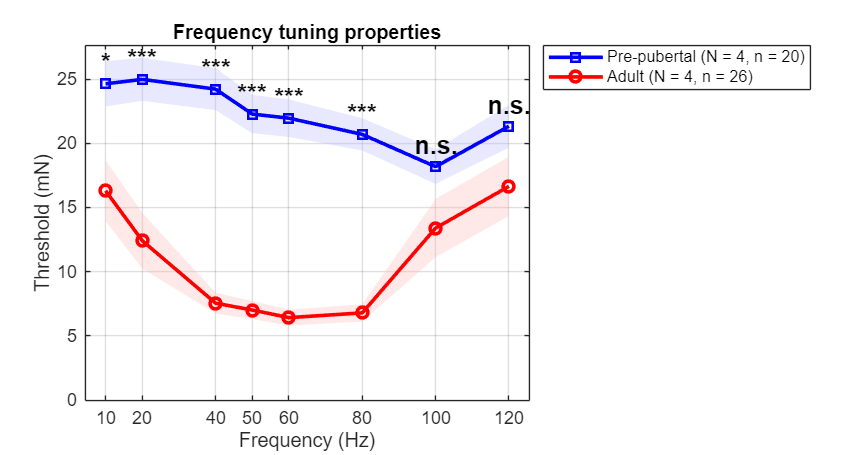

Legendname = input('Enter legend names (e.g., ["Pre-pubertal","Adult"]): ');
N = [4 4];  % number of animals for two groups
n = [size(Pre_data,1), size(Adult_data,1)];

Legendname = arrayfun(@(i) sprintf('%s (N = %d, n = %d)', ...
    Legendname(i), N(i), n(i)), 1:numel(Legendname), 'UniformOutput', false);

% ---- Create figure first, with final size ----
fi1 = figure('Units', 'pixels', 'Position', [100 100 1500 800]);

% ---- Create axes with fixed size ----
ax = axes('Parent', fi1, 'Units', 'normalized', ...
          'Position', [0.10 0.12 0.85 0.78]);
hold(ax, 'on');

% ---- Pre group: shaded SEM ----
x_pre = [freqs, fliplr(freqs)];
y_pre = [Pre_mean - Pre_SEM, fliplr(Pre_mean + Pre_SEM)];
hPreFill = fill(ax, x_pre, y_pre, [0.7 0.7 1], ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');

% ---- Adult group: shaded SEM ----
x_adult = [freqs, fliplr(freqs)];
y_adult = [Adult_mean - Adult_SEM, fliplr(Adult_mean + Adult_SEM)];
hAdultFill = fill(ax, x_adult, y_adult, [1 0.7 0.7], ...
    'FaceAlpha', 0.3, 'EdgeColor', 'none');

% ---- Mean lines ----
hPreLine = plot(ax, freqs, Pre_mean, '-square', 'LineWidth', 2, 'Color', [0 0 1]);
hAdultLine = plot(ax, freqs, Adult_mean, '-o', 'LineWidth', 2, 'Color', [1 0 0]);

% ---- Stars ----
y_star = max([Pre_mean; Adult_mean], [], 1) + 0.5;
for i = 1:length(freqs)
    text(ax, freqs(i), y_star(i), stars(i), ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', ...
        'FontSize', 14, ...
        'FontWeight', 'bold', ...
        'Color', [0 0 0]);
end

% ---- Formatting ----
xticks(ax, freqs);
xticklabels(ax, string(freqs));

xpad = 0.05 * range(freqs);
xlim(ax, [min(freqs)-xpad, max(freqs)+xpad]);

ylim(ax, [0, max([Pre_mean + Pre_SEM, Adult_mean + Adult_SEM]) + 1]);

xlabel(ax, 'Frequency (Hz)');
ylabel(ax, 'Threshold (mN)');
title(ax, 'Frequency tuning properties');

grid(ax, 'on');
box(ax, 'on');

% ---- Legend outside ----
lgd = legend(ax, [hPreLine, hAdultLine], Legendname, ...
    'Location', 'northeastoutside');

hold(ax, 'off');

figureName_allneuron = strcat(path,"\CombinedFrequencytuning_comparison.pdf");
exportgraphics(fi1, figureName_allneuron,"Resolution",600);

%Compare pre-pubertal and adult AUC
clear;
close all;

[Pre_file, path] = uigetfile( ...
    '\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Analysis\Calcium\AUC*.mat', ...
    'Select files','MultiSelect','off');
[Adult_file, path] = uigetfile( ...
    '\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Analysis\Calcium\AUC*.mat', ...
    'Select files','MultiSelect','off');

Pre_fname = fullfile(path, Pre_file);
Adult_fname = fullfile(path, Adult_file);
Pre_struct = load(Pre_fname);
Adult_struct = load(Adult_fname);

Pre_data = Pre_struct.Matrix;
Adult_data = Adult_struct.Matrix;

Pre_mean = mean(Pre_data,1);
Pre_SEM = std(Pre_data) ./ sqrt(size(Pre_data, 1));

Adult_mean = mean(Adult_data,1)

Adult_mean =    19.8508   29.7431   52.1816   64.4681   68.6673   55.1265   38.2159   20.5771


Adult_SEM = std(Adult_data) ./ sqrt(size(Adult_data,1));

freqs = [10 20 40 50 60 80 100 120];
pvals = zeros(length(freqs),1);
stats = cell(length(freqs),1);
stars = strings(length(freqs),1);
for i = 1:length(freqs)
    pre_freq = Pre_data(:,i);
    adult_freq = Adult_data(:,i);
    [h, p, ci, tstat] = ttest2(pre_freq, adult_freq);
    pvals(i) = p;
    stats{i} = tstat;
    if pvals(i) < 0.001
        stars(i) = "***";
    elseif pvals(i) < 0.01
        stars(i) = "**";
    elseif pvals(i) < 0.05
        stars(i) = "*";
    else
        stars(i) = "n.s.";   % optional: no significance
    end
end

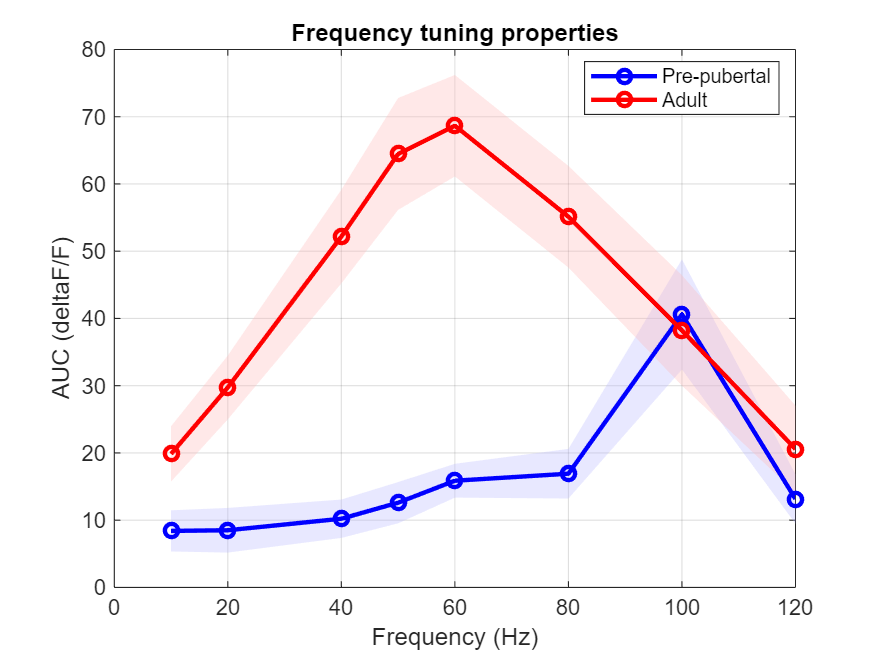

fi2 = figure; hold on;
x_pre = [freqs, fliplr(freqs)];
y_pre = [Pre_mean - Pre_SEM, fliplr(Pre_mean + Pre_SEM)];

hPreFill = fill(x_pre, y_pre, [0.7 0.7 1], ...   % light blue
    'FaceAlpha', 0.3, 'EdgeColor', 'none');

% ---- Adult group: shaded SEM ----
x_adult = [freqs, fliplr(freqs)];
y_adult = [Adult_mean - Adult_SEM, fliplr(Adult_mean + Adult_SEM)];

hAdultFill = fill(x_adult, y_adult, [1 0.7 0.7], ... % light red
    'FaceAlpha', 0.3, 'EdgeColor', 'none');

% ---- Plot the mean lines on top ----
hPreLine = plot(freqs, Pre_mean, '-o', 'LineWidth', 2, 'Color', [0 0 1]);
hAdultLine = plot(freqs, Adult_mean, '-o', 'LineWidth', 2, 'Color', [1 0 0]);

% y_star = max([Pre_mean; Adult_mean]) + max([Pre_SEM; Adult_SEM]);  % baseline height
% for i = 1:length(freqs)
%     text(freqs(i), y_star(i), stars(i), ...
%         'HorizontalAlignment','center', ...
%         'VerticalAlignment','bottom', ...
%         'FontSize',14,'FontWeight','bold','Color', [0.5 0.5 0.5]);
% end

% ---- Make it pretty ----
xlabel('Frequency (Hz)');
ylabel('AUC (deltaF/F)');
legend([hPreLine, hAdultLine], {'Pre-pubertal', 'Adult'}, 'Location', 'best');
title('Frequency tuning properties');
grid on;
box on;
hold off;

figureName_allneuron_AUC = strcat(path,"\CombinedFrequencytuning_AUC_comparison.pdf");
exportgraphics(fi2, figureName_allneuron_AUC,"Resolution",300);